# VolumeViewer

## Load in data

s2 = load('mristack.mat');

% Place data into a VolumeModel
volModel = wt.model.VolumeModel;
volModel.Name = 'mristack';
volModel.ImageData = s2.mristack;

% Provide the world coordinates from edge to edge
volModel.WorldExtent = [
    0 300 % Y dimension in mm
    0 300 % X dimension in mm
    0 150 % Z dimension in mm
    ];


## Create the widget

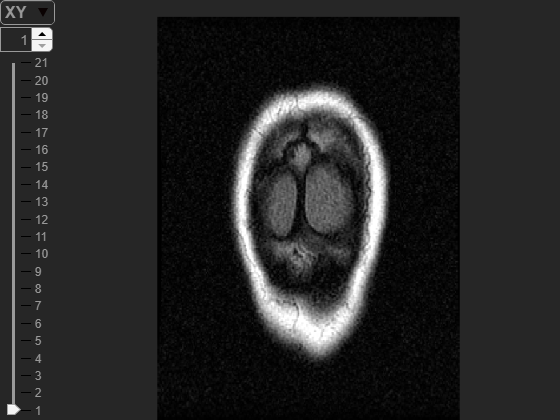

update


f = uifigure;
g = uigridlayout(f,'ColumnWidth',{'1x'},'RowHeight',{'1x'},'Padding',[0 0 0 0]);
obj = wt.VolumeViewer('Parent',g,'VolumeModel',volModel);
movegui(f,'northwest')

## Change the view plane to side view

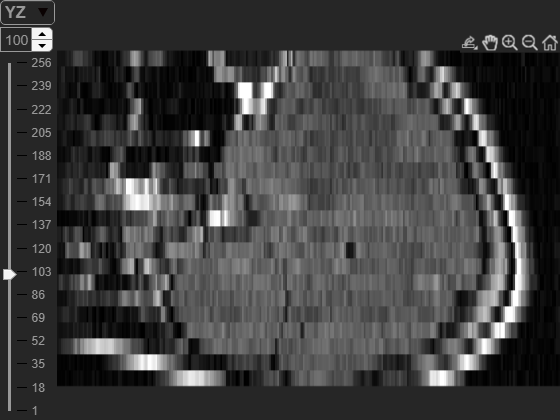

obj.View = 'yz';
obj.Slice = 100;

## Back to Normal

update


update


obj.View = 'xy';

*Copyright 2018-2020 The MathWorks, Inc.*